# Synchronization Algorithms implementation

### Introduction

From previous script, we have seen and implemented the main issues of synchronization. The aim of this script is to correct those errors. To do so, 2 main algorithms are needed : the gardner algorithm to track the correct time instant to sample and the DA frame acquisition to remove CFO and phase shift. 

The first algorithm to be implemented is the NDA (Non Data Aided) Gardner algorithm because this algorithm is resistant to both CFO and phase shift. CFO and phase shift will be corrected by the DA frame acquisition.  

clc; close all; clearvars;
addpath("C:\Users\François\Downloads\MA1\MC\project\ELEC-H-401-DVB-S2\1 Optimal communication chain over the ideal channel");

For the **DA frame acquistion**, known pilots will be sended before the data packets to estimate the ToA (Time of arrival) and the CFO. The choice of the pilot length must be high enough to correctly acquire the frame but not to long so that the data rate can be kept high.  

%% parameters
Nbit = 216*100;

Nbps = 1;    %Nombre of bits per symbol (1 = BPSK, 2 = 4QAM, 4 = 16QAM, 6 = 64QAM)
pilot_symbol_length = 24;
pilot_length = pilot_symbol_length*Nbps ; %20 in the course but here at 24 so it can be easily mapped.
pilot = randi(2,1,pilot_length)-1;
pilot_ratio = 0.1;
data_length = pilot_length/pilot_ratio -pilot_length; % 90% of a codeblock is the data
data_symbol_length = data_length/Nbps;
codeblock_length = data_length+pilot_length;

f_cut = 1e6; %Hz Cutoff frequency
fsymb = 2*f_cut;
T_symb = 1/fsymb;
M = 24; %Upsampling factor (au moins plus grand que 4) multiple de fsamp
fsamp = fsymb*M/2; % Sampling frequency (rule of thumb for the 10 25 times f_cut) Its the freq on which the conv of the filter and the signal will be done --> has to be the same !!!
EbNo = 6; %Energy of one by over the PSD of the noise ratio (in dB)
N_taps = 101; %number of taps of the filter
beta = 0.3; %Makes the window smoother as beta increases // roll-off factor given in the specifications

%% Bit Generator

bits = randi(2,1,Nbit)-1;
bits_save = bits;
pilot_offset = 25*Nbps;
%pilot_offset = randi(data_length/2,1,1);
pilot_offsetbits = randi(2,1,pilot_offset)-1;
bits_and_pilots = pilot_offsetbits;

for i = 1:data_length:Nbit
    bits_and_pilots = [bits_and_pilots pilot bits(i:i+data_length-1)]; 
end
bits = bits_and_pilots;

check_mult = mod(Nbit,Nbps);
if check_mult == 0
    bit_tx = bits;
else
    bit_tx = [bits  zeros(1,Nbps - check_mult)];
end
Nbit_tx = length(bit_tx);

%% Mapping
%Maps the bits into desired symbols in the complex plane 
if (Nbps > 1)
    symb_tx = mapping(bit_tx', Nbps, 'qam')';
    pilot_mapped = mapping(pilot',Nbps,'qam')';
else
    symb_tx = mapping(bit_tx', Nbps, 'pam')';
    pilot_mapped = mapping(pilot', Nbps, 'pam')';
end

%figure(12); grid on; title("Mapped signal in absolute value"); stem(abs(symb_tx));
%% Upsampling

upsampled_symb_tx = UpSampling(symb_tx,Nbit_tx,Nbps,M);


%% Transmitter Filter

filter = HalfrootNyquistFilter(fsamp,T_symb,N_taps); %So we compute de filter only 1 time as this is the same

signal_tx = conv(upsampled_symb_tx,filter);%Convolution of the signal with the filter
signal_tx1 = conv(upsampled_symb_tx(1:M),filter);


%figure(7); stem(abs(signal_tx)); title("transmited signal")
%signal_tx = upsampled_symb_tx;


%% Transmission Channel

%signal_rx = NoiseAddition(signal_tx,EbNo,fsamp,Nbit);      %With Noise
signal_rx = signal_tx;                              %Without Nosie

% signal_rx1 = NoiseAddition(signal_tx1,EbNo,fsamp,Nbps);      %With Noise
signal_rx1 = signal_tx1;      %With Noise

%fig_signal_tx = figure('Name','signal_tx','NumberTitle','off');plot(signal_rx,'b.');grid on;hold on;plot(signal_tx,'ro');


%% CFO and phase shift addition
fs_passband= 2e9; %Hz
CFO = 20; % CFO in ppm (2 to see something)
CFO = fs_passband*CFO*1e-6; %CFO in Hz
[signal_rx_CFO, phase_shift, time_shift] = Add_sync_errors(signal_rx,CFO,fsamp,M,Nbps);
%figure;subplot(1,2,1); scatter(real(signal_rx_CFO),imag(signal_rx_CFO)); axis equal; title("CFO and phase shift effects"); legend("CFO and phase shift"); subplot(1,2,2); scatter(real(signal_rx),imag(signal_rx)); axis equal; legend( "No CFO and phase shift")

%% Matched filter 
matched_filter = flip(filter); %Get the time reversal of the filter g(-t) 
upsampled_signal_rx = conv(signal_rx_CFO,matched_filter,'valid');
vanilla_upsampled_signal = conv(signal_rx,matched_filter,'valid');

### The Gardner Algorithm

*Code is in the GardnerDownsampler function*

The feedback loop implementation of the Gardner algorithm follows this recursive equation : 

## 
$$\hat{\epsilon}[n+1] = \hat{\epsilon}[n]+2 \kappa \Re\left[y_{\hat{\epsilon}[n]}[n-1 / 2]\left(y_{\hat{\epsilon}[n]}^{*}[n]-y_{\hat{\epsilon}[n-1]}^{*}[n-1]\right)\right]

(1)$$


##  Where $y_{\epsilon}[n] := \int^{\infty}_{-\infty}{r(t)g^{*}(t-nT -\epsilon T)} (2)$ 

In this code, $y_\epsilon [n]
$ is `signal_rx `and $\epsilon$ is the `time_shift `given in indices. 

(1) is interpreted has the estimation of the correct sample time shift. Once this time shift maximizes the signal energy, it is assumed to be the correct time shift.

We have to add the time shift in the matched filter to get (2) We therefore have to get rid of it after the matched filter.

The following graph shows how the algorithm works. 

## 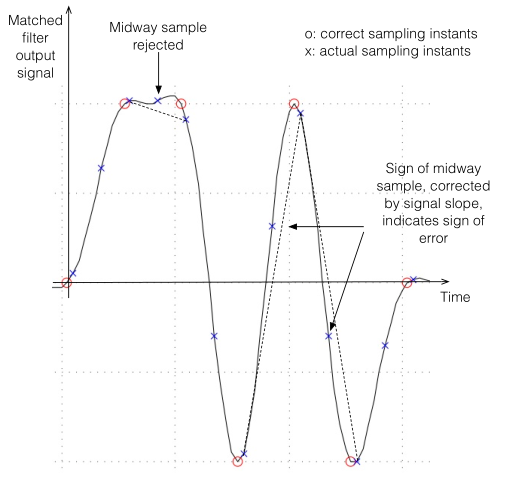

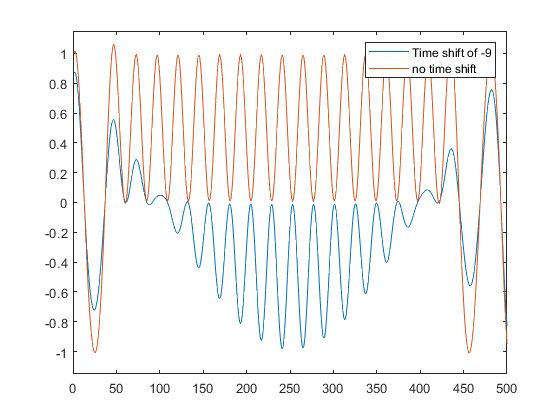

kappa = 0.02; %correction slope coefficient trade off time/noise reduction
figure; plot(real(upsampled_signal_rx)); hold on; plot(real(vanilla_upsampled_signal));
legend("Time shift of "+string(time_shift)  ,"no time shift");
xlim([0 500])
ylim([-1.15 1.15])

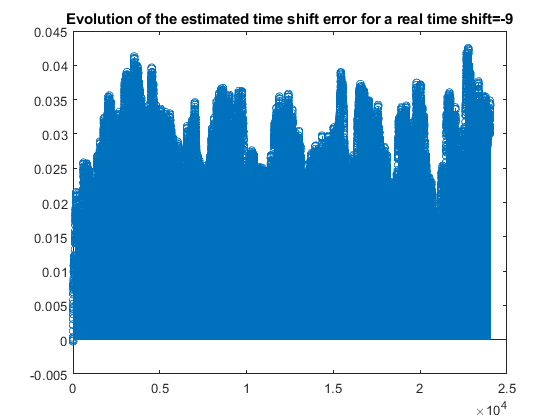


%upsampled_gardned_signal_rx = signal_rx_CFO;


[y,eps_hat] = Gardner(upsampled_signal_rx,M,kappa);
figure; stem(eps_hat);title("Evolution of the estimated time shift error for a real time shift="+string(time_shift));

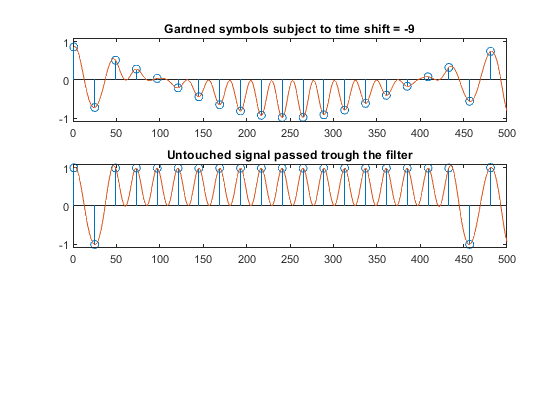


%% Downsampling
%symb_rx = DownSampling(upsampled_gardned_signal_rx,Nbit_tx,Nbps,M);
symb_rx_vanilla = DownSampling(vanilla_upsampled_signal,Nbit_tx,Nbps,M);
figure; subplot(3,1,1); stem(1:M:Nbit_tx*M/Nbps,real(y));hold on; plot(real(upsampled_signal_rx)); title("Gardned symbols subject to time shift = "+string(time_shift));
subplot(3,1,2);stem(1:M:Nbit_tx*M/Nbps,real(symb_rx_vanilla));hold on; plot(real(vanilla_upsampled_signal)); title("Untouched signal passed trough the filter");

subplot(3,1,1)
xlim([0 500])
ylim([-1.10 1.10])
subplot(3,1,2)
xlim([0 500])
ylim([-1.10 1.10])

## Da Frame acquistion

Has to be done after the Gardner algorithm to correct CFO and ToA problems. 

%% DA frame acquistion
K = 8;
[symb_rx,n_hat,df_hat,Dk] = Da_frame_acq(y,pilot_mapped,data_symbol_length,K,T_symb,Nbps,Nbit)

symb_rx =    0.9628 + 0.2669i   0.9544 + 0.2654i   0.9537 + 0.2673i   0.9607 + 0.2700i  -0.9628 - 0.2669i  -0.9548 - 0.2657i  -0.9506 - 0.2656i  -0.9511 - 0.2656i  -0.9507 - 0.2652i  -0.9542 - 0.2672i  -0.9609 - 0.2702i   0.9665 + 0.2689i   0.9611 + 0.2684i  -0.9734 - 0.2715i   0.9627 + 0.2688i   0.9612 + 0.2680i  -0.9694 - 0.2692i   0.9652 + 0.2691i  -0.9647 - 0.2692i   0.9647 + 0.2692i  -0.9651 - 0.2695i   0.9686 + 0.2715i  -0.9622 - 0.2688i  -0.9613 - 0.2680i   0.9694 + 0.2692i  -0.9652 - 0.2691i   0.9647 + 0.2692i  -0.9651 - 0.2695i   0.9686 + 0.2715i  -0.9622 - 0.2688i  -0.9613 - 0.2680i   0.9694 + 0.2692i  -0.9652 - 0.2691i   0.9647 + 0.2691i  -0.9651 - 0.2695i   0.9686 + 0.2715i  -0.9622 - 0.2688i  -0.9618 - 0.2683i   0.9729 + 0.2712i  -0.9592 - 0.2667i  -0.9549 - 0.2653i  -0.9537 - 0.2673i  -0.9610 - 0.2702i   0.9664 + 0.2689i   0.9608 + 0.2680i  -0.9694 - 0.2692i   0.9652 + 0.2691i  -0.9647 - 0.2691i   0.9647 + 0.2691i  -0.9651 - 0.2695i


n_hat =           25         265         505         745         985        1225        1465        1705        1945        2185        2425        2665        2905        3145        3385        3625        3865        4105        4345        4585        4825        5065        5305        5545        5785        6025        6265        6505        6745        6985        7225        7465        7705        7945        8185        8425        8665        8905        9145        9385        9625        9865       10105       10345       10585       10825       11065       11305       11545       11785


df_hat =     0.2513    1.1052   -0.1755    0.6783   -0.6025    0.2513    1.1052   -0.1755    0.6783   -0.6025    0.2514    1.1052   -0.1755    0.6783   -0.6024    0.2514    1.1053   -0.1755    0.6783   -0.6024    0.2514    1.1052   -0.1755    0.6783   -0.6024    0.2514    1.1052   -0.1755    0.6783   -0.6024    0.2514    1.1052   -0.1756    0.6783   -0.6025    0.2514    1.1052   -0.1755    0.6783   -0.6025    0.2514    1.1052   -0.1756    0.6783   -0.6025    0.2514    1.1052   -0.1755    0.6783   -0.6024


Dk =    0.0274 - 0.0331i   0.0280 - 0.0340i   0.1367 - 0.1653i   0.0273 - 0.0328i   0.0826 - 0.0996i  -0.0276 + 0.0336i  -0.1366 + 0.1651i   0.2481 - 0.3003i  -0.0277 + 0.0335i  -0.0830 + 0.1005i   0.3049 - 0.3687i  -0.0263 + 0.0320i  -0.1382 + 0.1673i   0.3052 - 0.3689i   0.0279 - 0.0328i  -0.3031 + 0.3674i   0.1961 - 0.2367i   0.0827 - 0.0995i  -0.3037 + 0.3675i   0.1950 - 0.2357i   0.1940 - 0.2343i  -0.4139 + 0.5004i   0.1405 - 0.1697i   0.0851 - 0.1027i  -0.6352 + 0.7683i   0.0850 - 0.1020i   0.1388 - 0.1673i  -0.3053 + 0.3691i   0.1383 - 0.1669i   0.2478 - 0.2994i  -0.2490 + 0.3007i   0.0286 - 0.0350i   0.1937 - 0.2339i  -0.2489 + 0.3004i   0.0276 - 0.0339i   0.1374 - 0.1658i  -0.1398 + 0.1687i   0.0261 - 0.0313i   0.1362 - 0.1644i  -0.1947 + 0.2353i   0.0259 - 0.0315i   0.1918 - 0.2321i  -0.1941 + 0.2351i   0.0810 - 0.0984i  -0.0283 + 0.0340i  -0.2489 + 0.3008i   0.1381 - 0.1676i   0.0276 - 0.0331i  -0.2484 + 0.3001i   0.0283 - 0.0341i
   0.0379 - 0.0804i   0.1144 - 0.2445i  -0.0

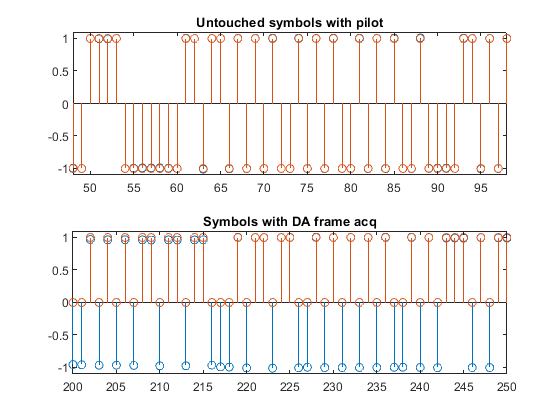

figure; subplot(2,1,1); stem(real(symb_rx_vanilla)); hold on; stem(real(symb_tx));title("Untouched symbols with pilot"); subplot(2,1,2); stem(real(symb_rx)); hold on; stem(bits_save); title("Symbols with DA frame acq")

subplot(2,1,1)
xlim([48 98])
ylim([-1.10 1.1])
subplot(2,1,2)
xlim([200 250])
ylim([-1.1 1.1])

%% Demapping
 
if (Nbps > 1)
    bit_rx = demapping(symb_rx', Nbps, 'qam')';
else
    bit_rx = demapping(real(symb_rx)', Nbps, 'pam')';
end

bit_down_scaled = bit_rx(1:Nbit);

%% Bits check

ErrorRatio = ErrorCalculator(bit_rx,bits_save)

ErrorRatio = 0

%figure; plot(symb_tx-symb_rx);title("error between symb_rx and symb_tx");

blublub